## SECTION 1: Training a visual cortex neuron to detect horizontal bars

In this exerise we will train a single neuron to detect vertical bars in its receptive field, simulating the firing properties of a simple cell in area V1 of the visual cortex. The preferred stimulus of a V1 simple cell is a bar of light that is oriented in a particular direction. For example, this V1 cell prefers a vertically oriented bar:

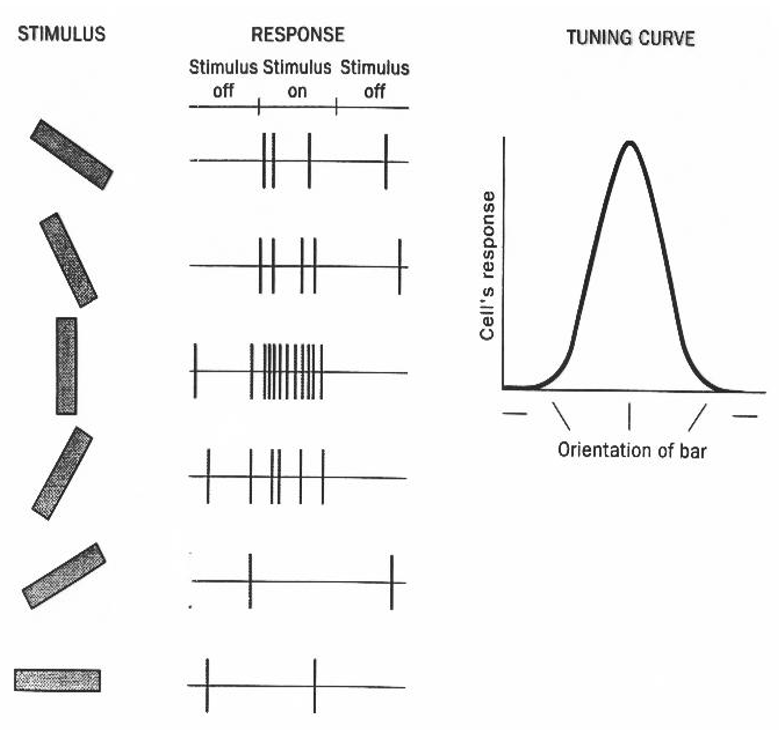

A V1 cell only responds to the bar of light if it has the preferred orientation AND is located in the center of its receptive field. The V1 cell is inhibited if the bar has the preferred orientation and is located at the edge of the receptive field (this is referred to as an "antipreferred" stimulus):  

 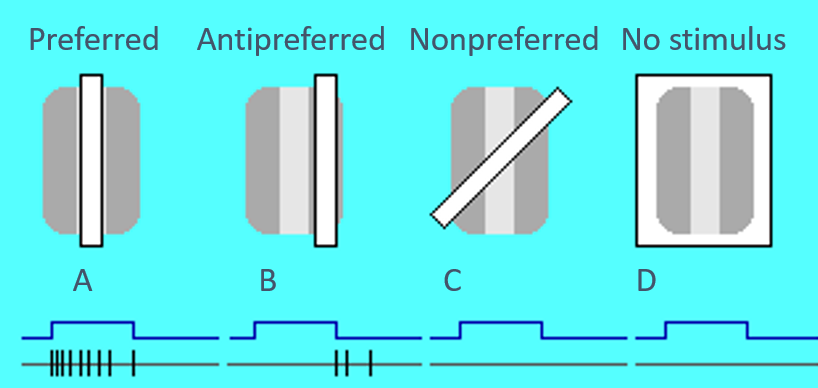

Here we will train a simulated V1 neuron to respond to vertical bars in the center of its receptive field. To do this, we will initialize the neuron's weights to random values and then present it with a large training set of visual stimuli. By a process of supervised learning, the neuron will change its weights to match the preferred stimulus. 

To load the training data and the target weight vector, click anywhere inside of the code block below and then click the 'Run Section' button in the menu bar. Make sure that you click 'Run Section' and not 'Run.'

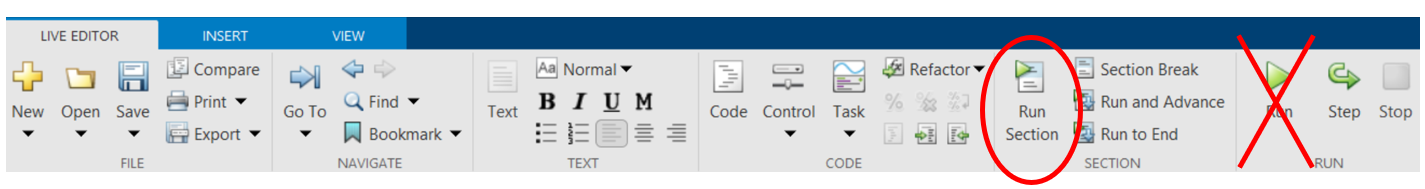

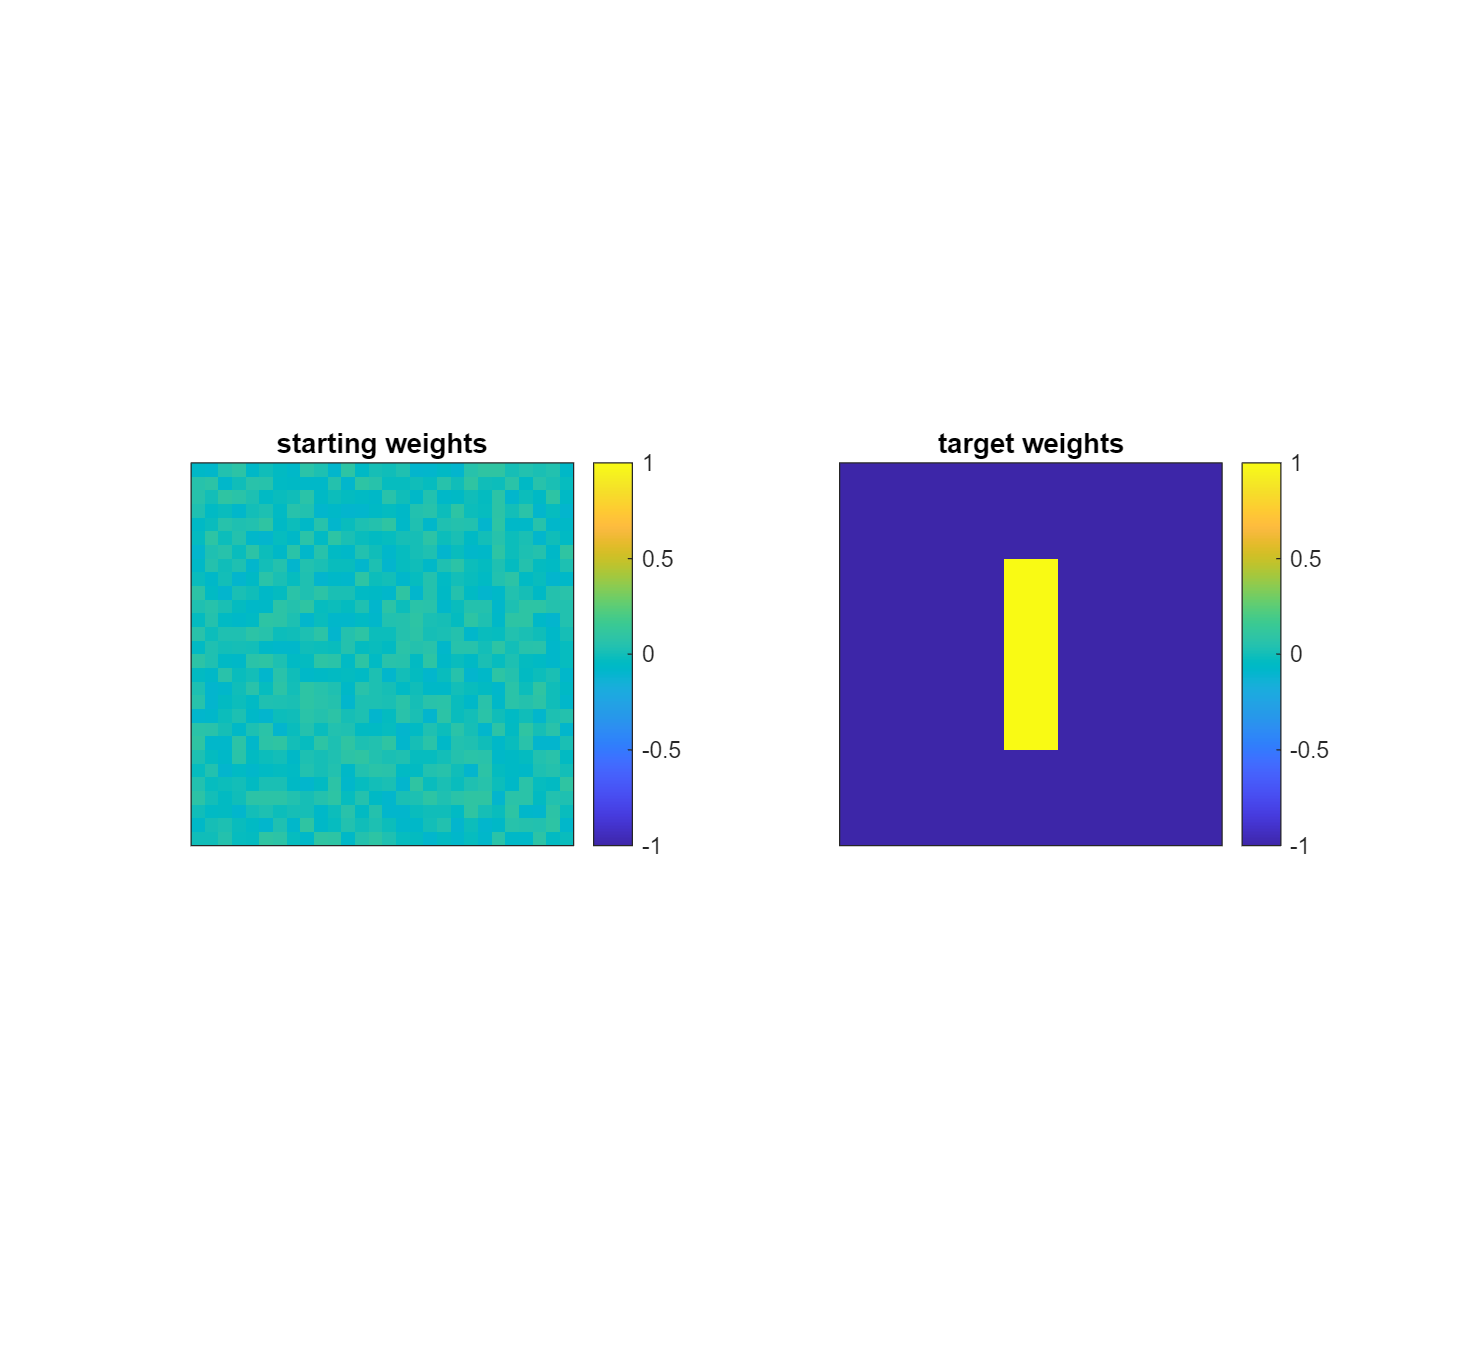

clear all; % clear all workspace variables

% set working directory to 'userpath' if it exists
if exist('C:\Users\ericy\OneDrive\Desktop\UCLA College stuffs\Senior Class\Winter\PSYCH 119D\MATLAB')
    workingfolder=[userpath '/Psych119D'];
else % otherwise use current directory
    workingfolder=pwd;
end

% load simulation data 
load('bardata.mat'); % swatting hand
try
    targetW=tgtW'; %rotate weights for a vertically oriented bar
    clear tgtW; %clear originally loaded weights 
end

%initialize input weights to small random values
W = .1*(rand(28)*2-1);  % create a matrix of random weights with values between -.1 and .1
b = 0; % initialize the bias term to 0

clf; %clear the display area

subplot(1,2,1); imagesc(W); %plot random initial weight matrix
axis square; caxis([-1 1]); colorbar; %make plot square, set color range 
set(gca,'XTick',[],'YTick',[]); %remove tick labels
title('starting weights');

subplot(1,2,2); imagesc(targetW); %plot target weight matrix 
axis square; colorbar; %make plot square, set color range  
set(gca,'XTick',[],'YTick',[]); %remove tick labels
title('target weights')

When you run the code, you will see a display of the random starting weights (left) and the final target weights (right) that the neuron will try to learn to detect vertical bars.  

## SECTION 2: Training images 

To learn the preferred stimulus, the neuron will be trained on a set of 400 images. To see the training images, click in the code window below and hit "Run Section." 

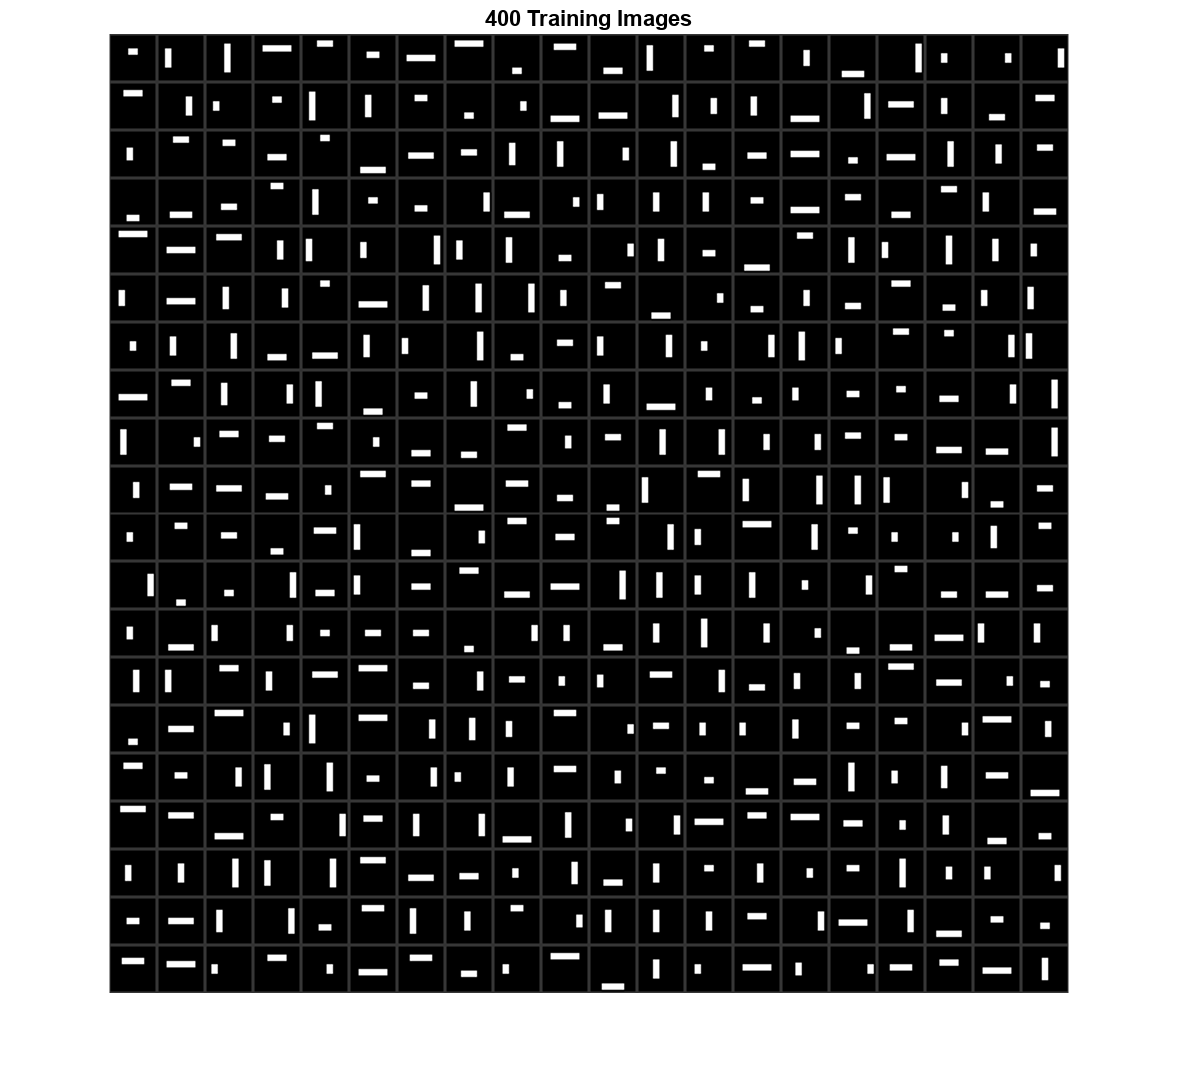

clf;
trainset=ones(30,30,400)*.2;
trainset(2:29,2:29,:)=permute(trainX,[2 3 1]);
montage(trainset, 'Size', [20 20]); 
title('400 Training Images')

As you can see, some of the training images are a good match to the preferred stimulus (vertical mars near the center of the receptive field), and others are a bad match (horiztonal bars or vertical bars that are not in the center of the receptive field). 

## SECTION 3: Creating a teacher for the linear regression neuron

The neuron will need a teacher (for supervised learning) to tell it which images from the training set are a good match to the preferred stimulus, and which are a bad match. The teacher needs to know the correct value of z for every training example, so that it can training the linear regression neuron by the gradient descent learning rule shown below.  

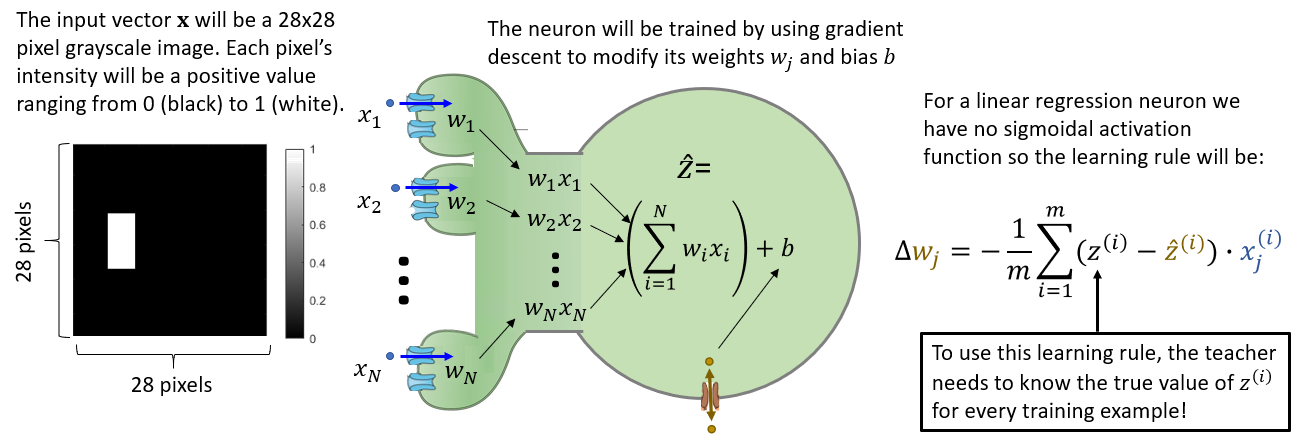

To compute and plot the target value z for each of the training images, click in the code window below and hit "Run Section." 

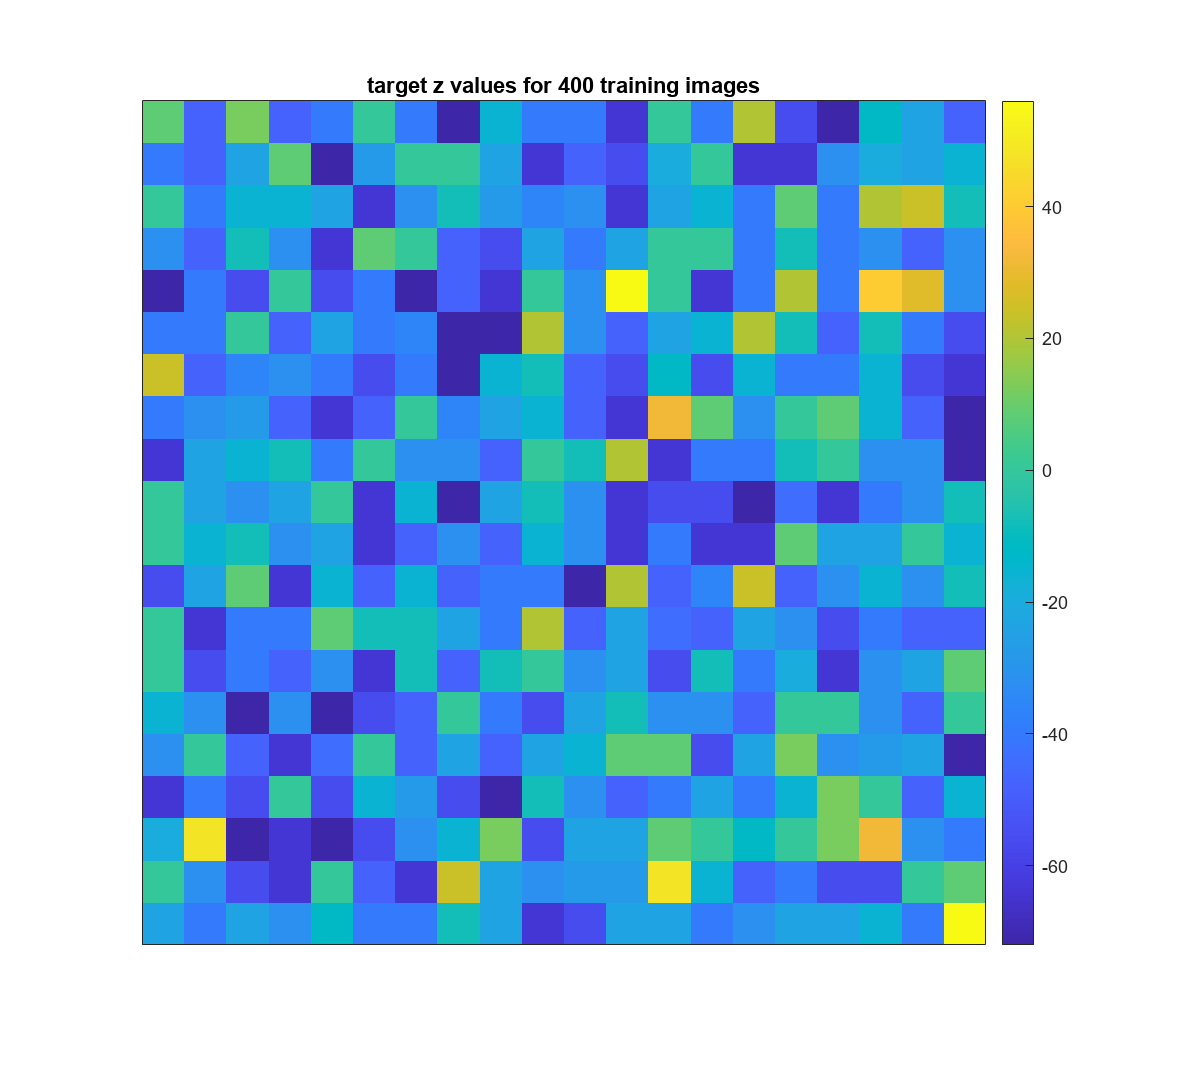

clf;
%----- compute target values of -----
M=size(trainX,1); % M equals the number of training images (height of the stack)
for i=1:M  % loop through all training images to compute their target z value from the known target weights
    X = squeeze(trainX(i,:,:));         % pull the ith training image from the stack
    XW = X.*targetW;                    % multiply the training image by the target weight vector
    z_tgt(i) = sum(XW(:));              % sum the products to compute the target z(i)
end
imagesc(reshape(z_tgt,20,20)'); 
axis square; colorbar; %make plot square, set color range  
set(gca,'XTick',[],'YTick',[]); %remove tick labels
title('target z values for 400 training images')
colormap parula;

The plot that appears above shows a grid of z values that matches the grid of training images above in section 2. Notice that training images that look like the preferred stimulus have large positive target z values (yellow squares), whereas training images that are a bad match to the preferred stimulus have large negative z values (dark blue squares). (NOTE: in this plot each square is a different TRAINING EXAMPLE IMAGE)

## SECTION 4: Measure pre-learning performance

Now that we know the target value of z for each training image, we are going to loop through the ENTIRE TRAINING SET (all 400 images) and compute the neuron's output, z_hat, for each image. These are the neuron's predicted values of z based upon its initially assigned small random weights.  We will also compute the difference between predicted output and target output: z - z_hat (which is the ERROR between the target versus predicted outputs).

To compute and plot the target and predicted values z for each of the training images, as well as the error, click in the code window below and hit "Run Section." 

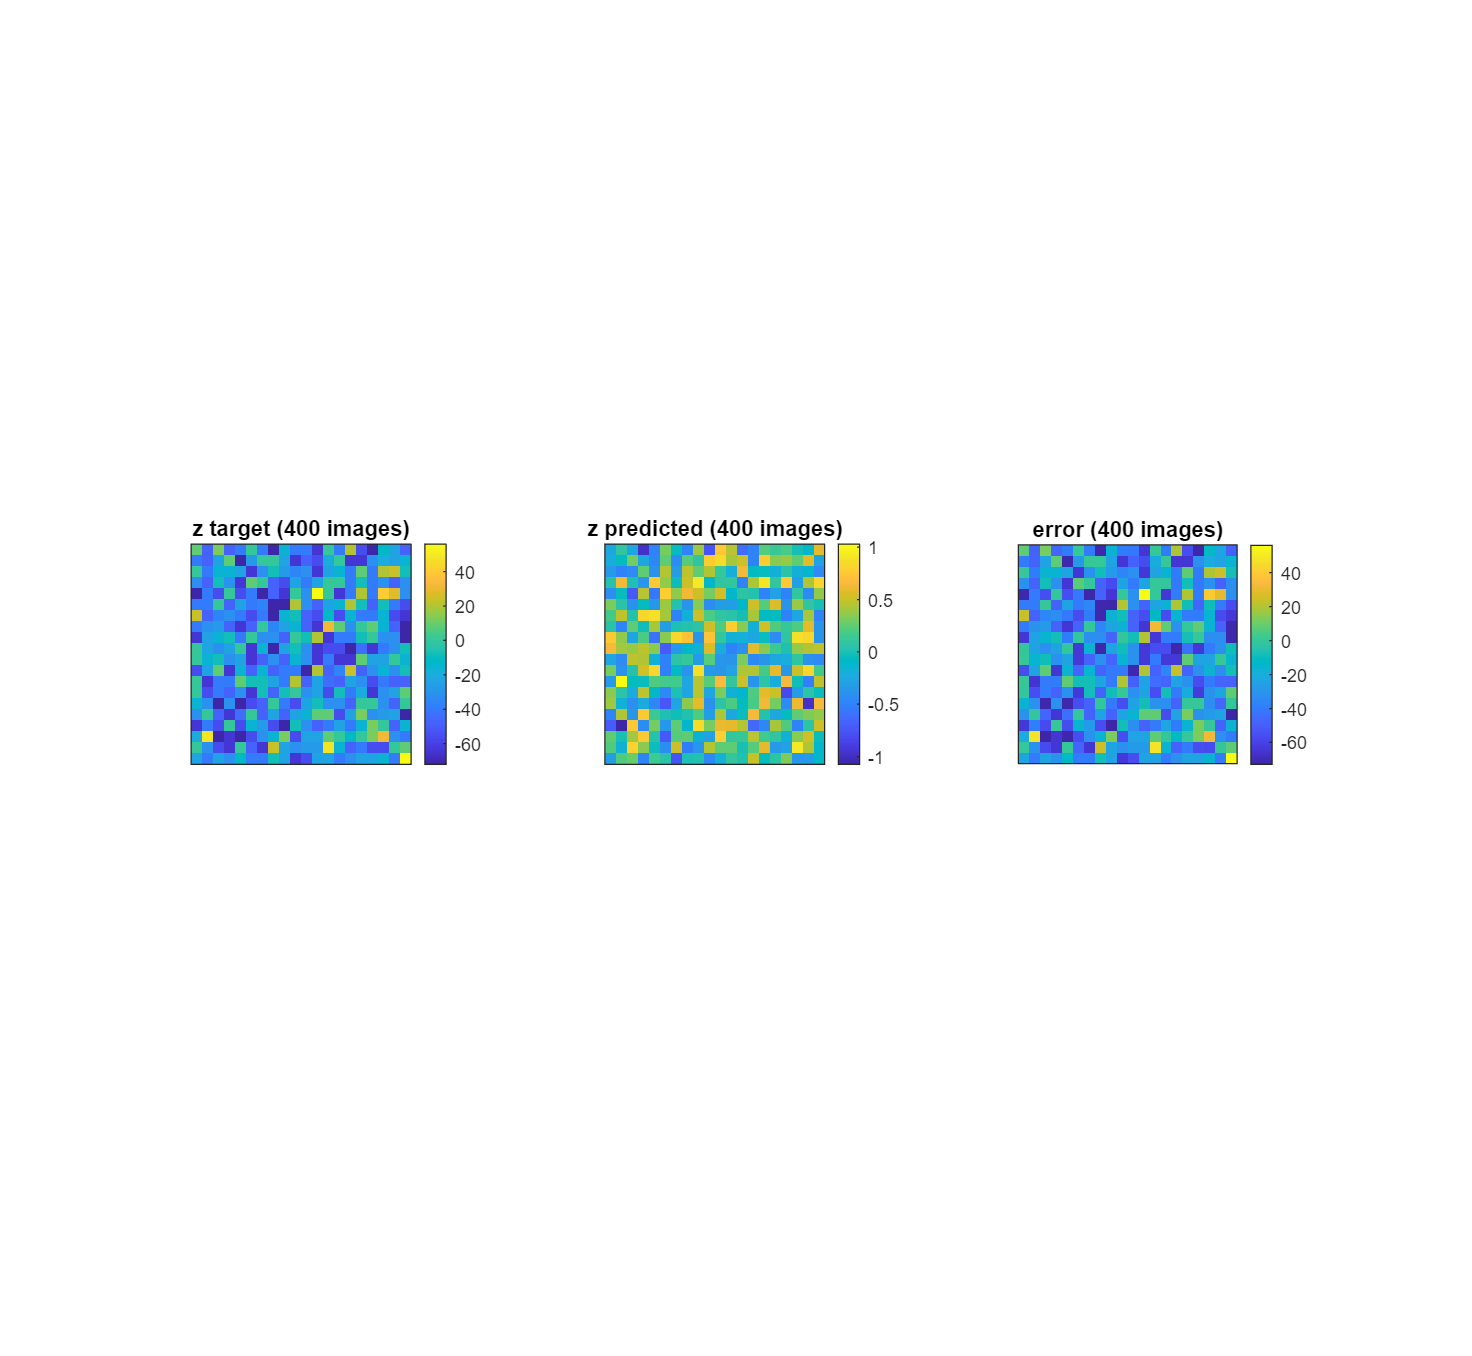

% compute errors and gradients for every item in the training set
for i = 1:M % loop through all items in the training set

    % these values are computed for each training example and not stored
    X = squeeze(trainX(i,:,:)); % pull image i from the training set
    z_hat(i) =  sum(sum(W .* X)) + b;  % compute transfer function for image i (predicted z)
    err(i) = (z_tgt(i) - z_hat(i));        % error for image i 

end % end of training set loop

clf;

subplot(1,3,1)
imagesc(reshape(z_tgt,20,20)'); 
axis square; colorbar; %make plot square, set color range  
set(gca,'XTick',[],'YTick',[]); %remove tick labels
title('z target (400 images)')
colormap parula;

subplot(1,3,2)
imagesc(reshape(z_hat,20,20)'); 
axis square; colorbar; %make plot square, set color range  
set(gca,'XTick',[],'YTick',[]); %remove tick labels
title('z predicted (400 images)')
colormap parula;

subplot(1,3,3)
imagesc(reshape(err,20,20)'); 
axis square; colorbar; %make plot square, set color range  
set(gca,'XTick',[],'YTick',[]); %remove tick labels
title('error (400 images)')
colormap parula;

You can see in the rightmost graph that many of the training examples produce large errors (yellow and dark blue squares). Through learning we hope to reduce these errors. (NOTE: in this plot each square is a different TRAINING EXAMPLE IMAGE)

## SECTION 5: Calculate how each weight changes on the first iteration of gradient descent

On the first iteration of gradient descent, each weight j will be adjusted by adding the following 'delta w' to its current value:

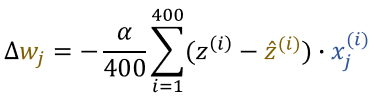

where 'alpha' is the learning rate. Notice that 'j' indexes each pixel in the image, so this equation states that each weight j will be adjusted by an amount that is proportional to the average (over all 400 training examples) of the intensity of pixel j times the neuron's output error for each individual image.    

To plot the starting weights, the computed amount by which each weight will change on the first iteration of gradient descent, and the new weights that will result after adding the delta w's to the old weights, click in the code window below and hit "Run Section." 

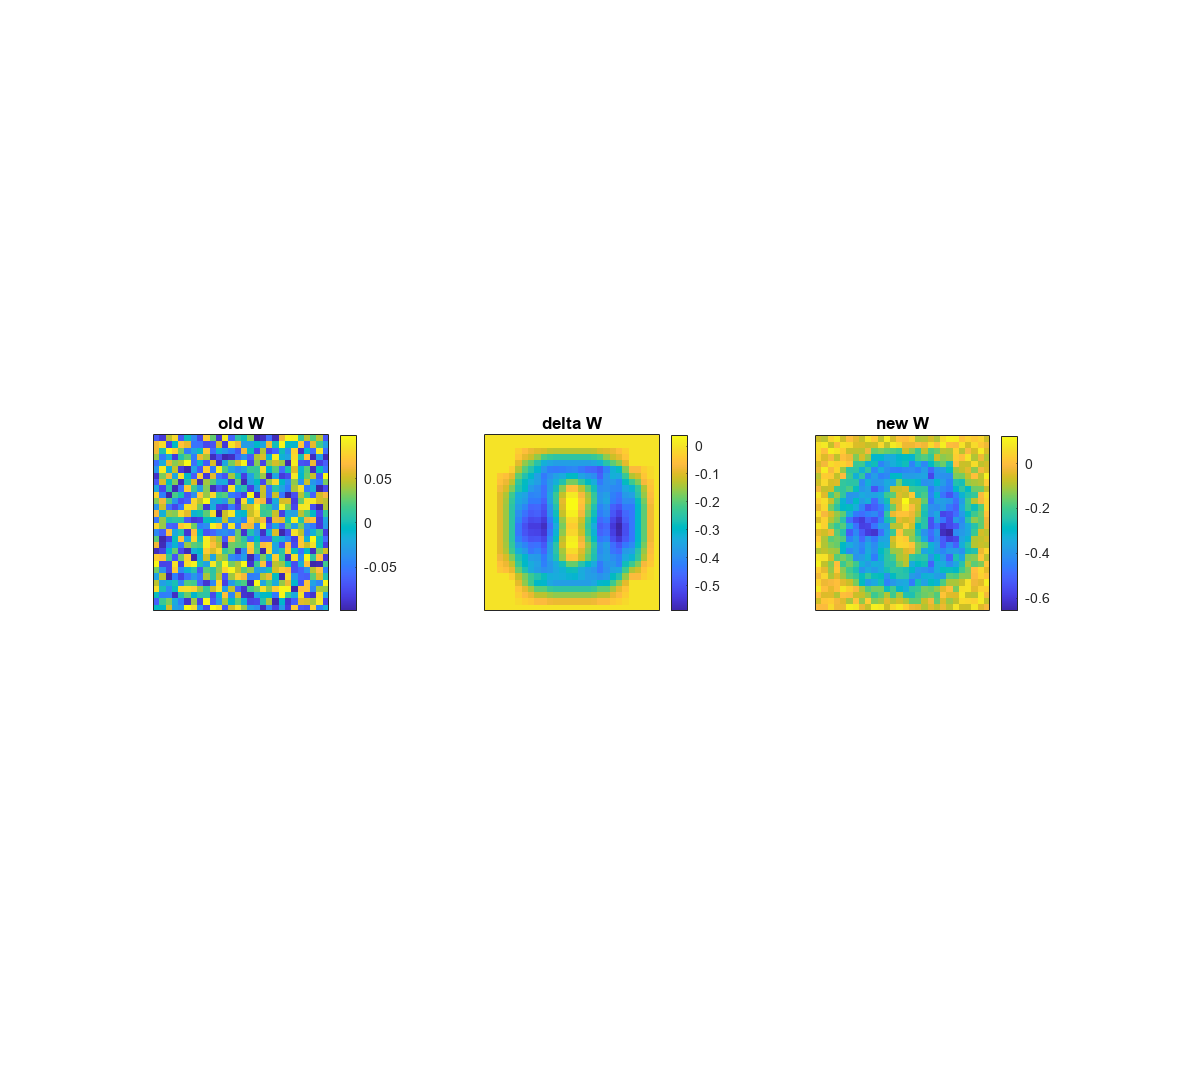

alpha=0.09; % set learning rate
 
clear z_hat err; 

% compute errors and gradients for every item in the training set

for i = 1:M % loop through all items in the training set

    % these values are computed for each training example and not stored
    X = squeeze(trainX(i,:,:)); % pull image i from the training set
    z_hat =  sum(sum(W .* X)) + b;  % transfer function for image i
    err = (z_tgt(i) - z_hat);        % error for image i

    % these values are derived from the error and stored, so that they can later be 
    % averaged over all training examples:
    loss(i) = err^2;            % squared error loss for image i
    gradw(i,:,:) = X * err;     % derivatives of loss with respect to W's for image i
    gradb(i) = err;             % derivative of loss with respect to bias for image i

end % end of training set loop

% Calculate the derivatives of the cost function as the average of the loss derivatives
dJ_db = mean(gradb);          %average the bias gradient over entire training set
dJ_dW = squeeze(mean(gradw)); %average weight gradients over entire training set

clf;

subplot(1,3,1)
imagesc(W); 
axis square; colorbar; %make plot square, set color range  
set(gca,'XTick',[],'YTick',[]); %remove tick labels
title('old W')
colormap parula;

subplot(1,3,2)
imagesc(alpha * dJ_dW); 
axis square; colorbar; %make plot square, set color range  
set(gca,'XTick',[],'YTick',[]); %remove tick labels
title('delta W')
colormap parula;

subplot(1,3,3)
imagesc(W + alpha * dJ_dW); 
axis square; colorbar; %make plot square, set color range  
set(gca,'XTick',[],'YTick',[]); %remove tick labels
title('new W')
colormap parula;

In this plot each square is a different PIXEL IN THE 28X28 RECEPTIVE FIELD. You can see that the 'delta W' matrix contains an image of the target weights (this is because the equation for delta W includes a term for the target output, and the target output comes from the teacher that "knows" what the correct output should look like). When you run this code with a small learning rate (such as the default value of .01), the new W matrix is not very different from the old W matrix (because the small alpha means we make very small changes to the weights). Try running with larger values of alpha. What happens to the new values of W as alpha increases? 

answer.Q1 = 1

answer = struct with fields:
    Q1: 1


## SECTION 6: Run 100 iterations of gradient descent

You can select the classifier type (linear or logistic) and the learning rate (alpha) using the controls below. Hit "Run Section" to rune the code. 

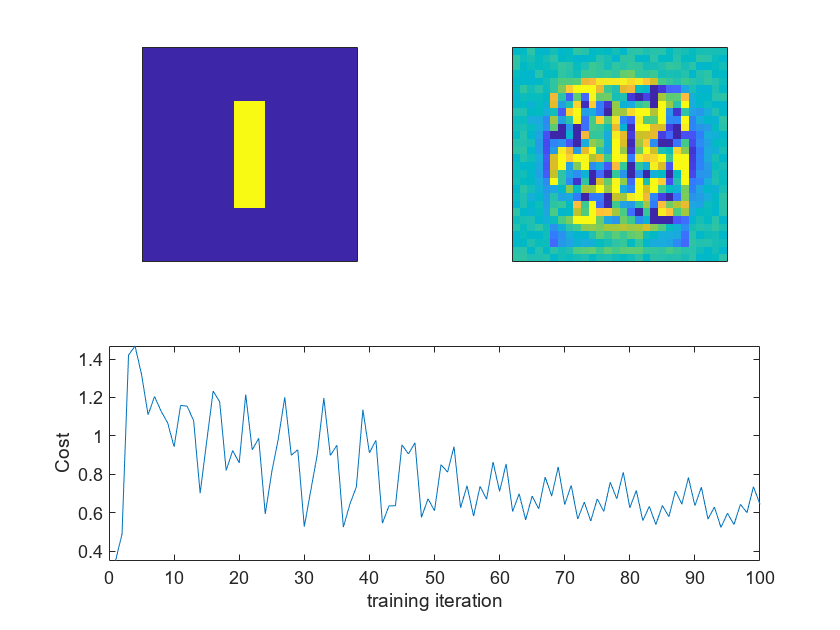

tasktype = 0;
alpha=45; % set learning rate

clf;

%initialize input weights to small random values
W = .1*(rand(28)*2-1);  % create a matrix of random weights with values between -.1 and .1
b = 0; % initialize the bias term to 0

subplot(2,2,1);  %select the upper right plot of the 2x2 array
hTgt = imagesc(targetW);                          %plot an image of the random inital weights matrix
set(gca,'XTick','','YTick','');      %erase the tick labels from the plot
caxis([-1 1]);                       %scale colors across the range from -1 to +1
axis square;                         %make the plot square

subplot(2,2,2);  %select the upper right plot of the 2x2 array
hW = imagesc(W);                          %plot an image of the random inital weights matrix
set(gca,'XTick','','YTick','');      %erase the tick labels from the plot
caxis([-1 1]);                       %scale colors across the range from -1 to +1
axis square;                         %make the plot square

subplot(2,2,[3 4]);
hJ = plot(1:100,NaN*[1:100]);
xlim([0 100]);
xlabel('training iteration');
ylabel('Cost');



for iter = 1:100 % loop through 100 training iterations

% compute errors and gradients for every item in the training set
for i = 1:M % loop through all items in the training set

    % these values are computed for each training example and not stored
    X = squeeze(trainX(i,:,:)); % pull image i from the training set
    z =  sum(sum(W .* X)) + b;  % transfer function for image i
    y =  1 / (1+exp(-z));       % activation function for image i
    if tasktype %linear neuron
        err = (z_tgt(i) - z);       % linear regression error
        loss(i) = err^2;            % squared error loss 
    else %logistic neuron
        tgty = (1/(1+exp(-z_tgt(i)))>.5);
        err = (tgty - y);                                        % logistic regression error
        loss(i) = -(tgty*log(y)+(1-tgty)*log(1-y));           % cross entropy loss
    end

    % these values are derived from the error and stored, so that they can later be 
    % averaged over all training examples:
    gradw(i,:,:) = X * err;     % derivatives of loss with respect to W's for image i
    gradb(i) = err;             % derivative of loss with respect to bias for image i

end % end of training set loop

% Calculate the derivatives of the cost function as the average of the loss derivatives
dJ_db = mean(gradb);          %average the bias gradient over entire training set
dJ_dW = squeeze(mean(gradw)); %average weight gradients over entire training set

% LEARNING: update weights by adding the cost derivatives (multipled by learning rate)
W = W + alpha * dJ_dW;
b = b + alpha * dJ_db;

% MSE cost for this iteration is the average MSE loss over all training examples
J(iter) = mean(loss)/2;

%plot the learning curve
hJ.YData(iter) = J(iter);
hW.CData = W;
ylim([0 max(J)]);

drawnow; % render the figure window so we can watch learning happen!

end % end of the training iteration loop

EXERCISE 1: Using the linear classifier setting, try to find a learning rate that gives the result shown below (including a similar learning rate in the bottom graph):

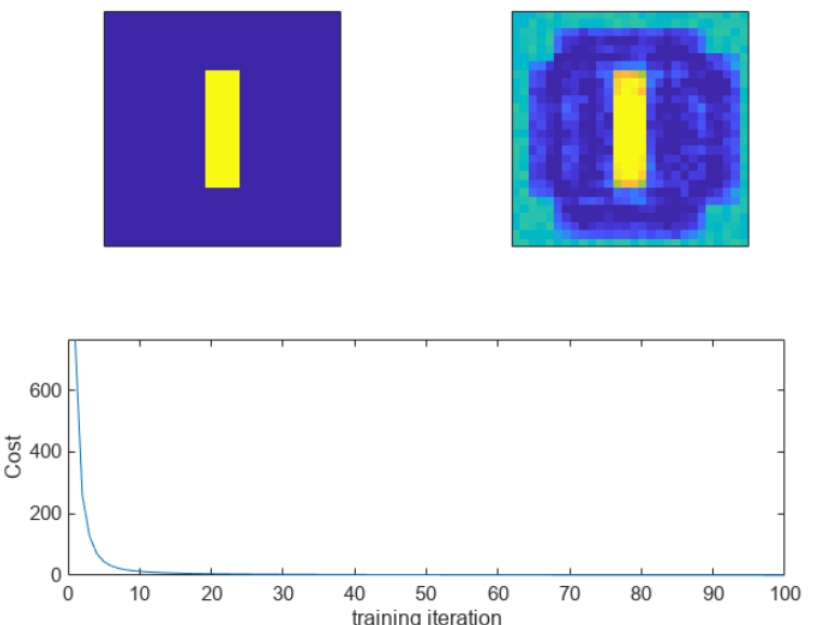

EXERCISE 2: Using the logistic classifier setting, try to find a learning rate that gives the result shown below (for this one ignore the bottom graph and try to match the top right graph):

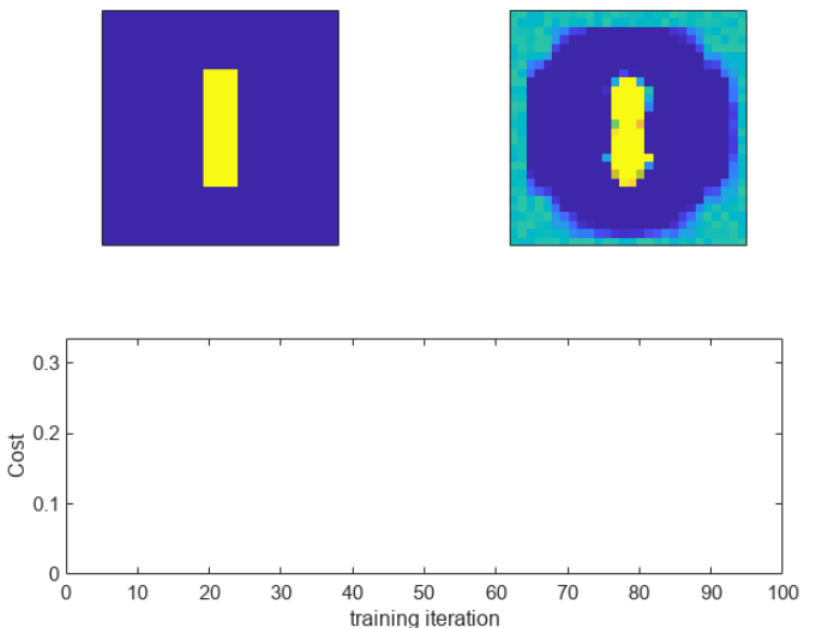

In the boxes below, type the values of the learning rates you found to get the requested results above:

answer.E1=0.1; % learning rate that gave the requested result for Exercise 1
answer.E2=45; % learning rate that gave the requested result for Exercise 2


## SECTION 7: Train the logisitic classifier to recognize antiworm stimuli

Now we will retrain the logisitic classifier neuron on the SAME DATA SET OF 400 IMAGES but this time the teacher will use different class labels for each training stimulua. Instead of labeling vertical bars in the center of the receptive field as class 1 and everything else as class 0, the teacher will label all vertical bars (regardless of their location in the receptive field) as class 1 and all horizontal bars as class 0. This is similar to the worm vs antiworm classification task that we learned about in class (except here the positive class is vertical bars so the classifier is trying to recognize antiworms):

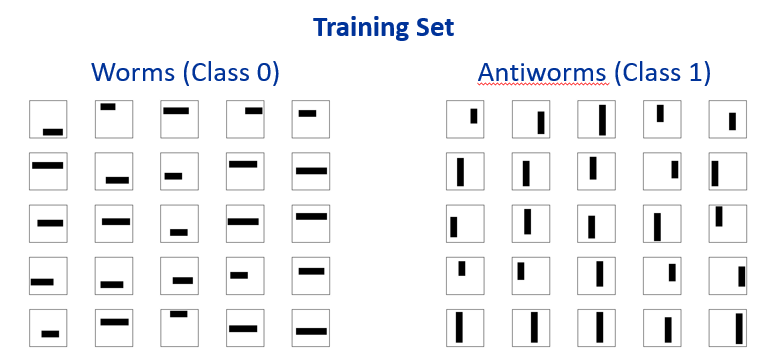

Hit "Run Section" to run the code.

tasktype = 0; % logistic regression
alpha=5; % set learning rate

clf;

%initialize input weights to small random values
W = .1*(rand(28)*2-1);  % create a matrix of random weights with values between -.1 and .1
b = 0; % initialize the bias term to 0

subplot(2,2,1);  %select the upper right plot of the 2x2 array
hTgt = imagesc(targetW);                          %plot an image of the random inital weights matrix
set(gca,'XTick','','YTick','');      %erase the tick labels from the plot
caxis([-1 1]);                       %scale colors across the range from -1 to +1
axis square;                         %make the plot square

subplot(2,2,2);  %select the upper right plot of the 2x2 array
hW = imagesc(W);                          %plot an image of the random inital weights matrix
set(gca,'XTick','','YTick','');      %erase the tick labels from the plot
caxis([-1 1]);                       %scale colors across the range from -1 to +1
axis square;                         %make the plot square

subplot(2,2,[3 4]);
hJ = plot(1:100,NaN*[1:100]);
xlim([0 100]);
xlabel('training iteration');
ylabel('Cost');
M=400;

for iter = 1:100 % loop through 100 training iterations

% compute errors and gradients for every item in the training set
for i = 1:M % loop through all items in the training set

    % these values are computed for each training example and not stored
    X = squeeze(trainX(i,:,:)); % pull image i from the training set
    z =  sum(sum(W .* X)) + b;  % transfer function for image i
    y =  1 / (1+exp(-z));       % activation function for image i
    if tasktype %linear neuron
        err = (z_tgt(i) - z);       % linear regression error
        loss(i) = err^2;            % squared error loss 
    else %logistic neuron
        tgty = horz(i);
        err = (tgty - y);                                        % logistic regression error
        loss(i) = -(tgty*log(y)+(1-tgty)*log(1-y));           % cross entropy loss
    end

    % these values are derived from the error and stored, so that they can later be 
    % averaged over all training examples:
    gradw(i,:,:) = X * err;     % derivatives of loss with respect to W's for image i
    gradb(i) = err;             % derivative of loss with respect to bias for image i

end % end of training set loop

% Calculate the derivatives of the cost function as the average of the loss derivatives
dJ_db = mean(gradb);          %average the bias gradient over entire training set
dJ_dW = squeeze(mean(gradw)); %average weight gradients over entire training set

% LEARNING: update weights by adding the cost derivatives (multipled by learning rate)
W = W + alpha * dJ_dW;
b = b + alpha * dJ_db;

% MSE cost for this iteration is the average MSE loss over all training examples
J(iter) = mean(loss)/2;

%plot the learning curve
hJ.YData(iter) = J(iter);
hW.CData = W;
ylim([min(J) max(J)]);

drawnow; % render the figure window so we can watch learning happen!

end % end of the training iteration loop

Would you say that the neuron successfully learned to recognize antiworms?

answer.Q2=0;

## SECTION 8: You are done! Submit your work to Canvas

To submit your assignment, follow three steps:

1) run the script below by clicking inside the code window and then hitting 'Run Section' (three graphs will appear below the code)

2) a file called '123456789_assignment3.mat' will be created in your 119D directory (with your SID in place of 123456789)

3) upload this file to Canvas to submit your completed assignment!

% SAVE FILE TO SUBMIT ON CANVAS

filename = ['405560409_assignment3.mat'];
save(['C:\Users\ericy\OneDrive\Desktop\UCLA College stuffs\Senior Class\Winter\PSYCH 119D\MATLAB/' filename],'answer');